### Import real data 

clear,clc;

load('ShulzeVorbModelDATA.mat') % folder: ece.kaya/MATLAB 

data = data - 100*1000;         % subtract the 100 ms before stim 
IRIs = diff(data,1,2);          % IRIs       
asyn = data - 450000;           % asynchrony

% data sample
I = IRIs(1,34:end)./1000;       % IRIs in miliseconds 
I = I';
N = length(I);

% tapping outlier removal
for i = 1:N
    if I(i) < 450 * 50/100 || I(i) > 450 * 150/100
        I(i) = [];
    end
end

## Wing & Kristofferson (1973) 

Wing, A. M., & Kristofferson, A. B. (1973). Response delays and the timing of discrete motor responses. *Perception & Psychophysics*, *14*(1), 5-12.

#### 
$${\mathrm{I}}_{\mathrm{j}} ={\mathrm{C}}_{\mathrm{j}} -{\mathrm{D}}_{\mathrm{j}-1} +{\mathrm{D}}_{\mathrm{j}}$$
                                         

Lag one covariance:


$$\begin{array}{l}
\gamma_I \left(1\right)=\mathrm{E}\left\lbrack \;\left({\mathrm{I}}_{\mathrm{j}} -\mu_{\mathrm{I}} \right)\left({\mathrm{I}}_{\mathrm{j}-1} -\mu_{\mathrm{I}} \right)\right\rbrack ;\\
\;\;\;\;\;\;\;\;\;={-\sigma^2 }_D 
\end{array}$$
 

Lag zero covariance:


$$\begin{array}{l}
\gamma_I \left(0\right)=\mathrm{E}\left\lbrack \;\left({\mathrm{I}}_{\mathrm{j}} -\mu_{\mathrm{I}} \right)\left({\mathrm{I}}_{\mathrm{j}} -\mu_{\mathrm{I}} \right)\right\rbrack ;\\
\;\;\;\;\;\;\;\;\;={\sigma^2 }_I \\
\;\;\;\;\;\;\;\;\;={\sigma^2 }_C +2{\sigma^2 }_D 
\end{array}$$


Lag one serial correlation:


$$\rho_I \left(1\right)=\frac{\gamma_I \left(1\right)}{\gamma_I \left(0\right)}\;$$


Timekeeper variance:


$${\sigma^2 }_{\mathrm{C}} =\gamma_{\mathrm{I}} \left(0\right)+2\gamma_{\mathrm{I}} \left(1\right)\;$$

$$\longrightarrow$$

$${{\mathrm{S}}^2 }_{\mathrm{C}} ={\mathrm{G}}_{\mathrm{I}} \left(0\right)+2{\mathrm{G}}_{\mathrm{I}} \left(1\right)$$


Motor variance:


$${\sigma^2 }_{\mathrm{D}} ={-\gamma }_{\mathrm{I}} \left(1\right)$$

$$\longrightarrow$$

$${{\mathrm{S}}^2 }_{\mathrm{D}} =-{\mathrm{G}}_{\mathrm{I}} \left(1\right)$$


Initialize two variables for lag-cov calculation

I_0 = I(1:end-1);
I_1 = I(2:end);

Long way 

lag_0 = sum((I_0 - mean(I_0)).*(I_0 - mean(I_0)))./ (length(I_0)-1);        % = var(I_0)
lag_1 = sum((I_1 - mean(I_1)).*(I_0 - mean(I_0)))./ (length(I_0)-1);        % = cov(I_0,I_1)

VAR_C = lag_0 + 2.*lag_1

VAR_C = -2.2640e+04

VAR_D = -lag_1

VAR_D = 2.1629e+04

Short way

clockvar = var(I_0) + 2.* cov(I_0,I_1);     
clockvar = clockvar(1,2)

clockvar = -2.2640e+04

motorvar = -cov(I_0,I_1);
motorvar = motorvar(1,2)

motorvar = 2.1629e+04

cov(I_0,I_1,1)

ans = 	1.0e+04 *

    1.9908   -2.0884
   -2.0884    2.2173



var(I)

ans = 2.2201e+04

*Note: *


$$\left\lbrack \begin{array}{cc}
\mathrm{cov}\left(A,A\right) & \mathrm{cov}\left(A,B\right)\\
\mathrm{cov}\left(B,A\right) & \mathrm{cov}\left(B,B\right)
\end{array}\right\rbrack$$


Lag-1 autocorrelation (serial correlation) ($\rho_I \left(1\right)$):

acorr_1 = lag_1 ./ lag_0

acorr_1 = -1.0490

Autocovariance ([https://www.mathworks.com/matlabcentral/fileexchange/35915-autocovariance](https://www.mathworks.com/matlabcentral/fileexchange/35915-autocovariance))

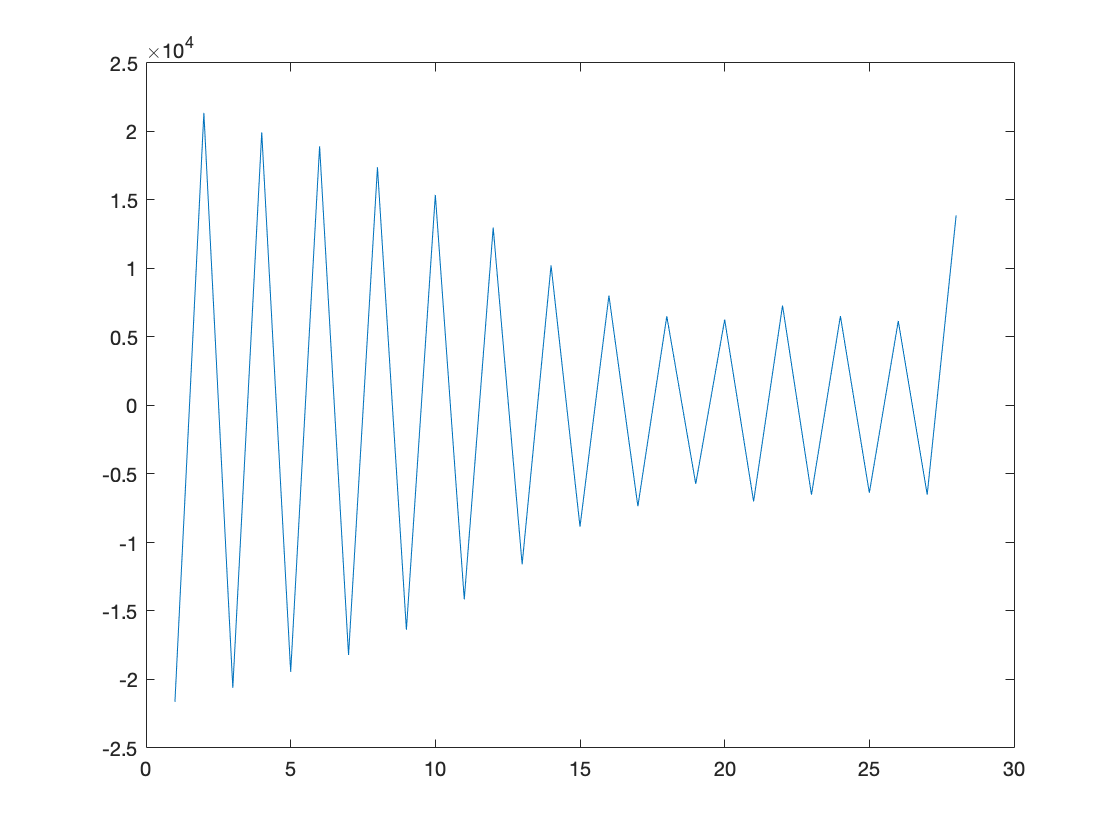

plot(autocov(I_1,I_0))

Simulation 


$${\mathrm{I}}_{\mathrm{j}} ={\mathrm{C}}_{\mathrm{j}} -{\mathrm{D}}_{\mathrm{j}-1} +{\mathrm{D}}_{\mathrm{j}}$$


% ???

## Semjen, Schulz  & Vorberg (2000)

Semjen, A., Schulze, H. H., & Vorberg, D. (2000). Timing precision in continuation and synchronization tapping. *Psychological Research*, *63*(2), 137-147.

### **Model**

#### Base model:  $I_n =T_n +M_{n+1} -M_n$ 

#### Model with error correction:  $I_n =\left(T_n -\alpha A_n -\beta A_{n-1} \right)+M_{n+1} -M_n$ 

${\mathrm{I}}_{\mathrm{n}}$ : inter-response-interval (ITI)

${\mathrm{A}}_{\mathrm{n}}$: asynchrony (asyn = tap onset - metronome onset) 

    ${\mathrm{T}}_{\mathrm{n}}$: timekeeper / brain clock >> mean(T) & std(T)

    $\mathrm{M}$: motor delay >> mean(M) & std(M)

    $\alpha \;:$fixed proportion to subtract from the last sync. error

    $\beta :$fixed proportion to subtract from the next-to-the-last sync. error

### **Simulations**

#### Continuation 


$${\mathrm{I}}_{\mathrm{n}} ={\mathrm{T}}_{\mathrm{n}} +{\mathrm{M}}_{\mathrm{n}+1} -{\mathrm{M}}_{\mathrm{n}}$$


*"Each variable is generated from a gamma distribution with k  = 4 and scaled to give variances of m = 5^2 and t = 7^2 or 15^2."*

k = 4;
vm = 5^2;
vt = [7^2 15^2];

*"A simulated continuation experiment involved sequences of 35 responses each, (N = 34 IRIs)." *

NI = 35;

*For a given parameter combination, Ns = 800 such sequences were generated.*

Nseq = 800;

vti = 15^2

for s = 1:Nseq
    
    M = gamrnd(k,sqrt(vm/k),[NI 1]);

    T = gamrnd(k,sqrt(vti/k),[NI-1 1]);
    
    I = [];
    
    for n = 1:34
        I(n) = T(n) + M(n+1) - M(n);
    end

    I_0 = I(1:end-1);
    I_1 = I(2:end);
    
    % Biased estimates
    lag0 = var(I_0);
    lag1 = cov(I_0,I_1);
    lag1 = lag1(1,2);
    
    m_est(s,1) = -lag1;
    t_est(s,1) = lag0 + 2*lag1;
    

*From each IRI series, we calculated **unbiased** estimates of m and t (see Vorberg & Wing, 1996). *

    % Unbiased estimates
    N = length(I_0);
    a = (N-1)/N;
    b = -2*(N-1)/N^2;
    c = -1/N;
    d = 1-(1-1/(N/(N-1)))*(2/N);
    
    unb_lag0 = ( d* lag0 - b*lag1)/(a*d - b*c);
    unb_lag1 = ( c* lag0 - a*lag1)/(b*c - a*d);
    
    m_est_unb(s,1) = -unb_lag1;
    t_est_unb(s,1) = unb_lag0 + 2*unb_lag1;
    
end

figure,
subplot(2,1,1)
histogram(m_est)
subplot(2,1,2)
histogram(m_est_unb)

figure,
subplot(2,1,1)
histogram(t_est)
subplot(2,1,2)
histogram(t_est_unb)


*We determined the frequency with which the variance estimators assumed negative values. *

prop_negvalues(1,1) = (length(m_est_unb(m_est_unb < 0)))/Nseq

*Variance estimates were negative in 8.25% of the experiments with t = 7^2 and m = 5^2, but the percentage rose to 30.5% when the timekeeper variance was increased to t = 15^2 [better]	*		

clear,clc;

#### Synchronization


$${\mathrm{I}}_{\mathrm{n}} =\left({\mathrm{T}}_{\mathrm{n}} -\alpha {\mathrm{A}}_{\mathrm{n}} -\beta {\mathrm{A}}_{\mathrm{n}-1} \right)+{\mathrm{M}}_{\mathrm{n}+1} -{\mathrm{M}}_{\mathrm{n}}$$
 	

Timekeeper intervals and motor delays were generated as in continuation...  

**Fig. 2 **Estimator variability in the second-order model. Histo- grams and scatter plots of pa- rameter estimates in N = 1000 simulated experiments with t 􏰄= 100, m 􏰄= 25, alpha 􏰄= .4 and beta = .3 

k = 4;
vm = 25;
vti = 100

vti = 100

alpha = 0.4;
beta =0.3;

A simulated experiment consisted of Ns 􏰄= 100 sequences of 31 responses each (yielding N 􏰄= 30 asynchronies).

Nseq = 100;
NI = 31;

for s = 1:1 % = 1:Nseq
        
    M = gamrnd(k,sqrt(vm/k),[NI 1]);
    T = gamrnd(k,sqrt(vti/k),[NI-1 1]);

            A crucial assumption is that the timekeeper mean is approximately set to the metronome period and need not be adjusted 

%     metronome = mean(T); % Molly selected mean(gamma) in general which is ~ 14. ??
%     
%     A = [];
%     I = [];
%     
% 
%     
%     for n = 2:30

                    ...As a simulated series unfolded, the metronome-tap asynchrony was calculated for each tap and used to correct the up-coming time-keeper interval.

%         
%         I(n) = T(n) - alpha*A(n-1) - beta*A(n-2) + M(n+1) - M(n); % tapped to correct previous tap's error
%     end

end

I = 18.1283

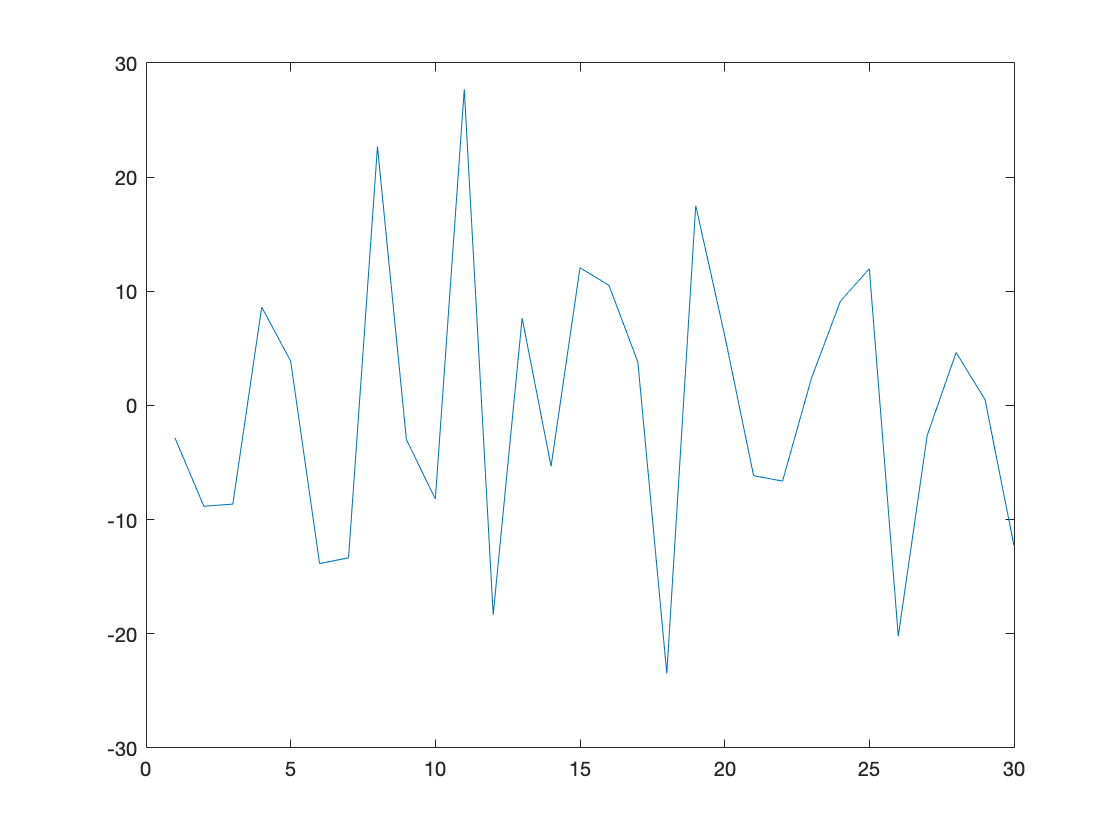


plot(A) %to test

Fig. 1 Predicted variance and serial correlations of the asynchronies A(n) (top) and the inter-response intervals I(n) (bottom) as a function of the first and second-order correction parameters. 

The x-axis indicates the value of alpha. The value of beta is indicated by line style (solid: beta =􏰄 0, dashed: beta =􏰄 .1, dotted: beta =􏰄 .2, dot-dash: b 􏰄 􏰂X1, dot-dot-dash: b 􏰄 􏰂X2)

ans = 154.0960

ans =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   Na

ans =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   Na

For each series, we calculated the sample ACVF of the asynchronies and averaged them across all Ns series. 

Parameters were estimated by fitting the model to the mean ACVF of the simulated data at lags 0 through 3; details are described in the Model fit and parameter estimates section. 